format compact;
format short e;

intervalle1 = [0,12.553518037837161];
intervalle2 = [0,6.448366808446808];
intervalle3 = [0,12.553518037837161];
nbrpas = [1055,1883,2272]; % Modifier le nombre de pas!


% Conditions initiales 1:
z1 = [-2.499999883, 0.0, 0.0, 2.100046263];
[temps1,pos1] = rk4(@f3Corps, intervalle1, z1, nbrpas(1));

% Conditions initiales 2:
z2 = [0.952281734, 0.0, 0.0, -0.957747254]; 
[temps2,pos2] = rk4(@f3Corps, intervalle2, z2, nbrpas(2));

% Conditions initiales 3:
z3 = [3.147603117, 0.0, 0.0, -3.07676285];
[temps3,pos3] = rk4(@f3Corps, intervalle3, z3, nbrpas(3));


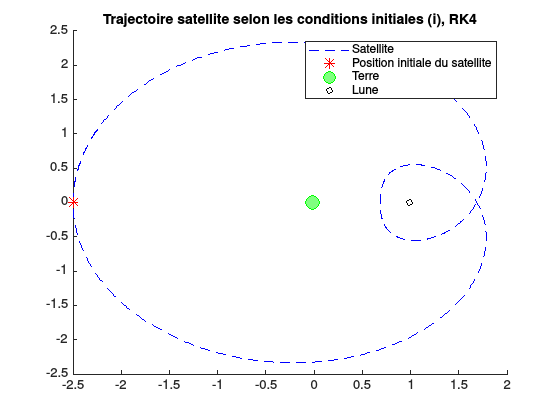

figure(1);
clf;
hold on;
plot(pos1(:,1),pos1(:,2),'b--')
plot(z1(1),z1(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (i), RK4')

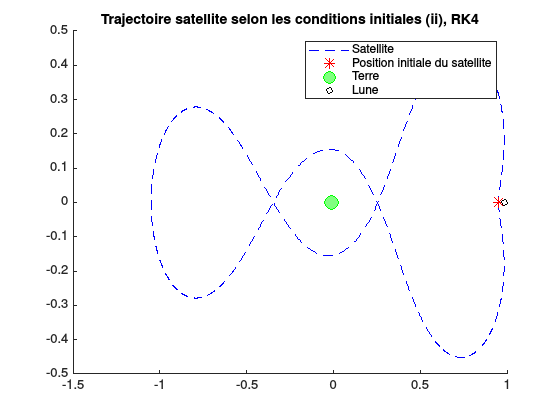



figure(2);
clf;
hold on;
plot(pos2(:,1),pos2(:,2),'b--')
plot(z2(1),z2(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (ii), RK4')

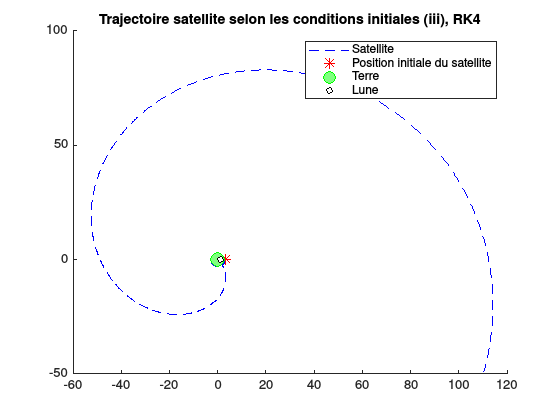


figure(3);
clf;
hold on;
plot(pos3(:,1),pos3(:,2),'b--')
plot(z3(1),z3(2),'r*','MarkerSize',8,'MarkerFaceColor',[0.2,0.2,0.8]);
plot(-mu,0,'go','MarkerSize',10,'MarkerFaceColor',[0.5,1,0.5]);
plot(1-mu,0,'ko','MarkerSize',4,'MarkerFaceColor',[1,1,1]);
hold off;
legend('Satellite','Position initiale du satellite','Terre','Lune')
title('Trajectoire satellite selon les conditions initiales (iii), RK4')